# Dot cloud method

## 0. Setting parameters 

clear;close all;
FILE_NAME_BKGD = 'APR08-P00-200Hz-150us-4800us-4mmPb-step0.01MeV-nml';
FILE_NAME_SMPL = 'APR08-P23-200Hz-150us-4800us-4mmPb-step0.01MeV-nml';
disp(['BKGD file name: ',FILE_NAME_BKGD]);

BKGD file name: APR08-P00-200Hz-150us-4800us-4mmPb-step0.01MeV-nml


disp(['SMPL file name: ',FILE_NAME_SMPL]);

SMPL file name: APR08-P23-200Hz-150us-4800us-4mmPb-step0.01MeV-nml


ENERGY_AXIS = [0.01:0.01:12]';
OUTLIER_THRESHOLD = 3; % times of variance out which the dots are regard as outlier
ACC_STABLE_TIMESTAMP = 150;

ROI.Cl35a = [195-15,195+15]; % Channel in normalized spectrum
ROI.Cl35b = [611-15,611+15];
ROI.Cl35c = [662-15,662+15];
ROI.N14a = [1083-15,1083+15];
ROI.N14a1 = [1083-15,1083+15];
ROI.N14b = [527-15,527+15];
ROI.TEST = [1125,1125];
ROI_TITLE.Cl35a = '1.959MeV';
ROI_TITLE.Cl35b = '6.111MeV';
ROI_TITLE.Cl35c = '6.620MeV';
ROI_TITLE.N14a = '10.829MeV';
ROI_TITLE.N14a1 = '10.829MeV';
ROI_TITLE.N14b = '5.269MeV';
ROI_TITLE.TEST = 'test';

Defined ROI(s): 

Cl35a: 1950keV±150keV;

Cl35b: 6110keV±150keV;

Cl35c: 6620keV±150keV;

NOTICE: The titles and x/y labels of following figures show what ROIs are used. 

ROI_SELECTED = {'Cl35b','Cl35c'};

% Keep ROIs in ROI_SELECTED
nameTmp = fieldnames(ROI);
for i = 1:length(nameTmp)
    if ~ismember(nameTmp{i},ROI_SELECTED)
        ROI = rmfield(ROI,nameTmp{i});
        ROI_TITLE = rmfield(ROI_TITLE,nameTmp{i});
    end
end
ROI = orderfields(ROI);
ROI_TITLE = orderfields(ROI_TITLE);
ROI_NAMES = fieldnames(ROI_TITLE);
TEST_DETECTION_TIME = [1,2,5,10,30]; % Unit: detection time of one ".spe" file
%TEST_DETECTION_TIME = 1:30;
N_ROC_POINT = 500;

## 1. Import data and data pre-processing 

### 1.1 Import data

Spectra should be normalized in advance.

bkgd = loadnormalizedseq(FILE_NAME_BKGD);
if isequal(bkgd,-1)
    error('Error: Normalized background file can not be read');
end
smpl = loadnormalizedseq(FILE_NAME_SMPL);
if isequal(smpl,1)
    error('Error: Normalized sample file can not be read');
end

### 1.2 Pre-processing

Delete the outliers in the spectra sequences. Counts of the spectra's sum and of the ROI sum are used and illustrated.

bkgd = deleteoutlier(bkgd,ACC_STABLE_TIMESTAMP,ROI,OUTLIER_THRESHOLD,0);
smpl = deleteoutlier(smpl,ACC_STABLE_TIMESTAMP,ROI,OUTLIER_THRESHOLD,0);

### 1.3 Show spectra with and without illicit objects

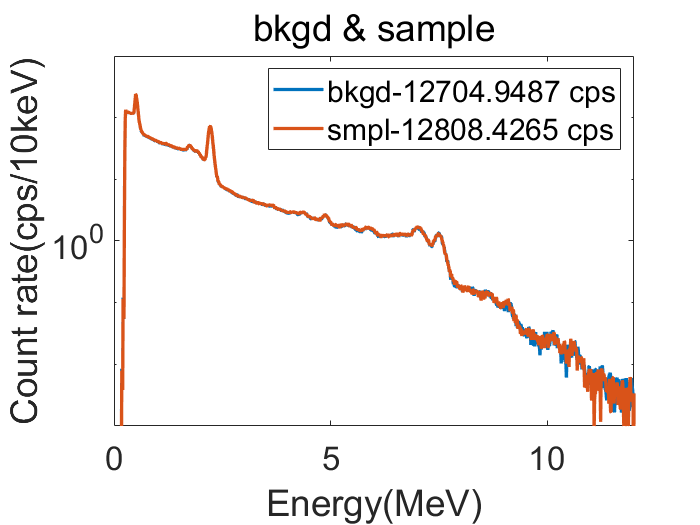

figure;
semilogy(ENERGY_AXIS,sum(bkgd,2)/size(bkgd,2),'LineWidth',2);hold on;
semilogy(ENERGY_AXIS,sum(smpl,2)/size(smpl,2),'LineWidth',2);
xlabel('Energy(MeV)');
ylabel(['Count rate(cps/',num2str(1000*(ENERGY_AXIS(2)-ENERGY_AXIS(1))),'keV)']);
legend(['bkgd-', num2str(sum(sum(bkgd))/size(bkgd,2)),' cps'], ...
    ['smpl-',num2str(sum(sum(smpl))/size(smpl,2)),' cps']);
xlim([0 12]);ylim([1e-3 1e3]);
title('bkgd & sample');
set(gca,'FontSize',20);
hold off;

## 2. Dot Cloud Method

REMEMBER: Everything here is trying to transport a list of spectra into a list of VALUABLE index. 

DO NOT THINK COMPLICATED

Input parameters here:

normalized spectrums - `bkgd/smpl`

Region of interest - `ROI/ROI_TITLE`

### 2.1 Dot cloud figure and index

Each figure intuitively shows the dot clouds of spectra with and without illicit object in different measuring time. 

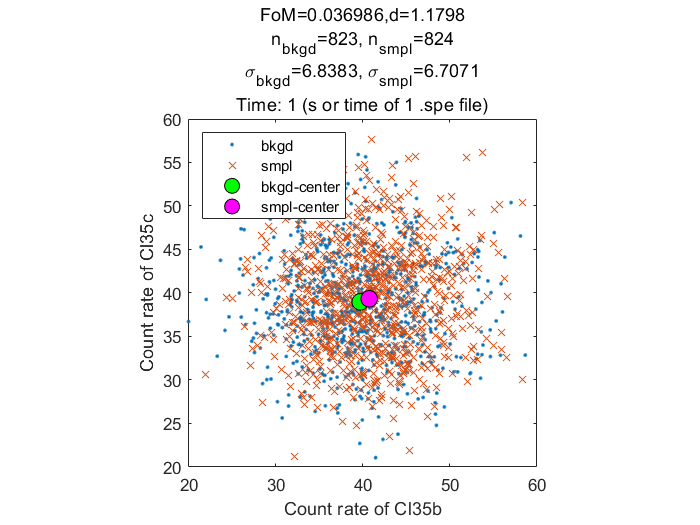

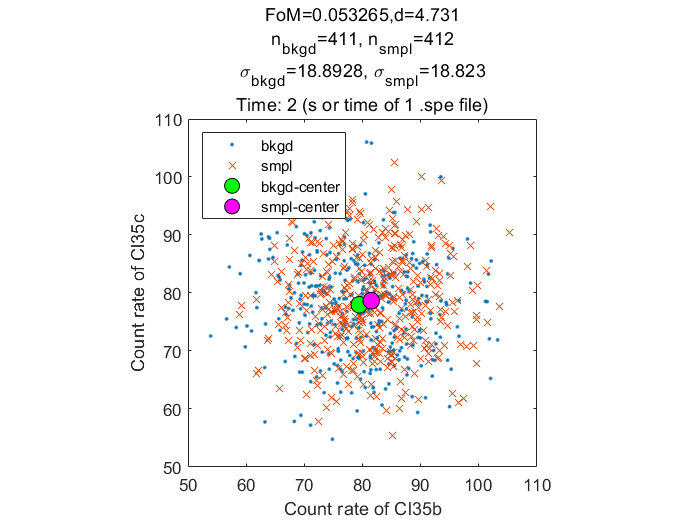

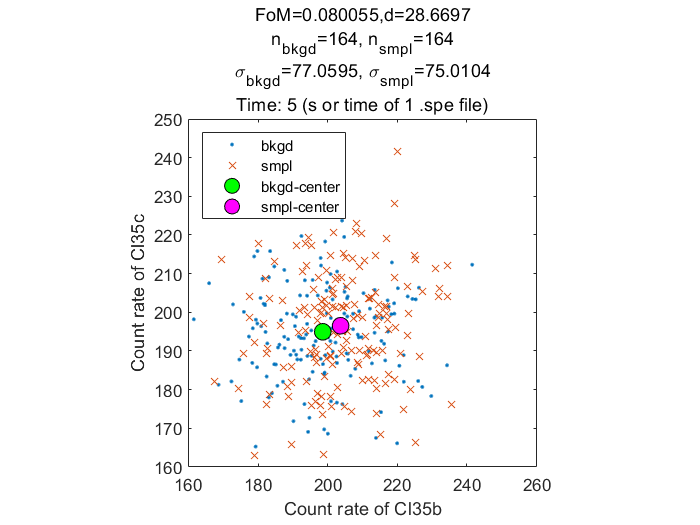

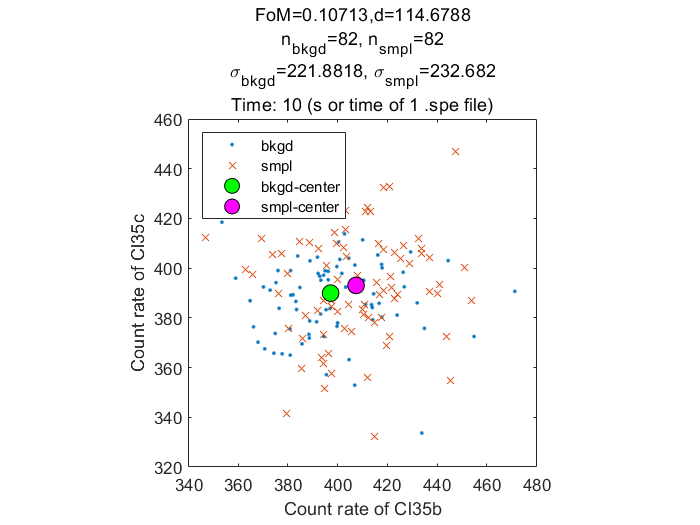

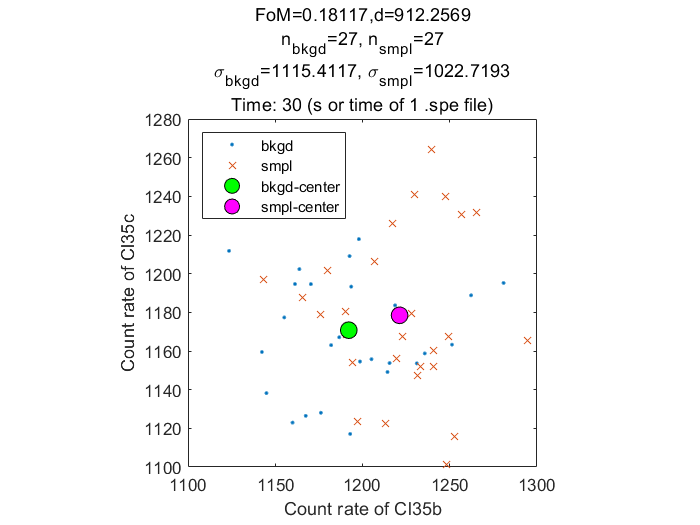

for iTime = TEST_DETECTION_TIME % Unit: detection time of one ".spe" file
    bkgdDots{iTime,1} = dotlist(bkgd,iTime,ROI);
    smplDots{iTime,1} = dotlist(smpl,iTime,ROI);
    discParam = cclFoM(bkgdDots{iTime,1},smplDots{iTime,1});
    coreIndex{iTime,1} = discParam.index1;
    coreIndex{iTime,2} = discParam.index2;
    switch length(fields(ROI))
        case 2
            figure;
            plot(bkgdDots{iTime,1}(1,:),bkgdDots{iTime,1}(2,:),'.');hold on;
            plot(smplDots{iTime,1}(1,:),smplDots{iTime,1}(2,:),'x');
            % Plot cloud center
            plot(discParam.center1(1),discParam.center1(2),'o','MarkerSize',10,'MarkerEdgeColor','k','MarkerFaceColor','g');% Green for dataSet1
            plot(discParam.center2(1),discParam.center2(2),'o','MarkerSize',10,'MarkerEdgeColor','k','MarkerFaceColor','m');% Pink for dataSet2
            xlabel(['Count rate of ',ROI_NAMES{1}]);
            ylabel(['Count rate of ',ROI_NAMES{2}]);
            title({['FoM=',num2str(discParam.FoM),',d=',num2str(discParam.dis),]; ...
                ['n_b_k_g_d=',num2str(size(bkgdDots{iTime,1},2)), ...
                ', n_s_m_p_l=',num2str(size(smplDots{iTime,1},2))];
                ['\sigma_b_k_g_d=',num2str(std(discParam.index1,1)), ...
                ', \sigma_s_m_p_l=',num2str(std(discParam.index2,1))]; ...
                ['Time: ',num2str(iTime),' (s or time of 1 .spe file)']});
            legend('bkgd','smpl','bkgd-center','smpl-center','Location','northwest');
            axis square;
            hold off;
        otherwise
            disp('Notice: Can not plot ROI~=2 yet');
    end
end

## 2.2 Dot cloud ROC

### 2.2.1 seperation according to orginal index

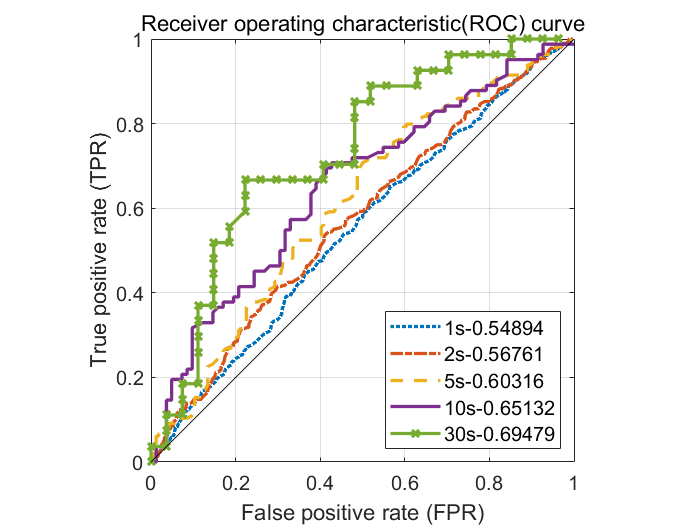

for iTime = TEST_DETECTION_TIME % Unit: detection time of one ".spe" file
    [rocRaw{iTime,1},aucRaw(iTime,1)] = ...
        rocraw(coreIndex{iTime,1},coreIndex{iTime,2},N_ROC_POINT);
end
handle = plotmyroc(rocRaw,aucRaw,TEST_DETECTION_TIME);

### 2.2.2 seperation according to Gaussian distribution

Assuming the data points in dot clouds are 2D sample sets of Gaussian distributions. Using these Gaussian distributions to plot the ROC curve.

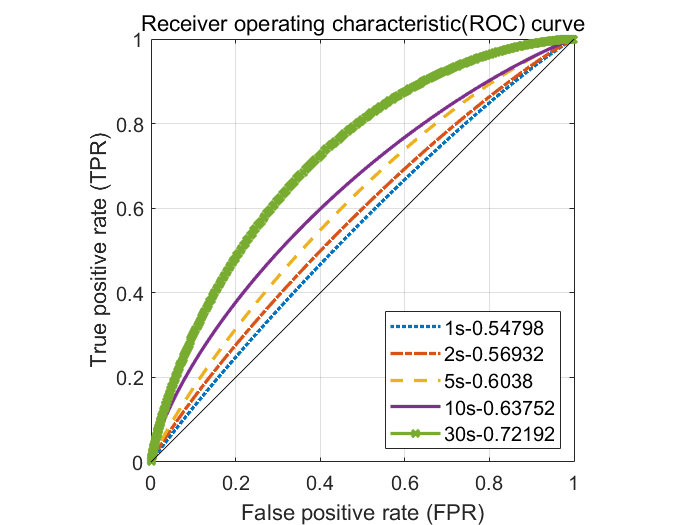

for iTime = TEST_DETECTION_TIME % Unit: detection time of one ".spe" file
    [rocGauss{iTime,1},aucGauss(iTime,1)] = rocgauss(coreIndex{iTime,1},coreIndex{iTime,2},N_ROC_POINT);
end
handle = plotmyroc(rocGauss,aucGauss,TEST_DETECTION_TIME);

## 3. 向量投影法

暂无标准能谱

### 3.1 计算线性投影方向

return;% 向量投影法需基于可靠的基准谱，此处采用2019JUL14所测不同元素未评估的基准谱
load('lib_projVector1200ch.mat'); % 
projectionVec.centers = mycenters(bkgd,smpl);
projectionVec.fisher = myfisher(bkgd,smpl); % 矩阵接近奇异值的问题 来自于 矩阵病态

projectionVec.fisherP21 = fisher2019aug06P21aug04t1snml;
projectionVec.fisherP22 = fisher2019aug06P22aug04t1snml;
projectionVec.centersP21 = centers2019aug06P21aug04t1snml;
projectionVec.centersP22 = centers2019aug06P22aug04t1snml;
fff = projectionVec.fisher;
% projectionVec.fisher1eminus7 = fff.*(abs(fff)>1e-7);

### 3.2 不同投影方向效果

projectionVecNames = fieldnames(projectionVec);
for iVec = 1:length(fields(projectionVec))
    for iTime = TEST_DETECTION_TIME % Unit: detection time of one ".spe" file
        [Jrule(iTime,iVec),aucProjection(iTime,iVec)] = ...
            estimatevector(combinespectra(bkgd,iTime,1),combinespectra(smpl,iTime,1), ...
            getfield(projectionVec,projectionVecNames{iVec}));
    end
end
handle = plotmyvec(projectionVec,projectionVecNames);
handle = plotdiscvalue(aucProjection,projectionVecNames);
handle = plotdiscvalue(Jrule,projectionVecNames);